a = input('Ingrese el valor del intervalo a: ');
b = input('Ingrese el valor del intervalo b: ');

e = input('Ingrese el valor del error: ');
while e <= 0
    disp('Error: El error no puede tomar valores negativos o ser cero.');
    e = input('Ingrese un valor positivo para el error: ');
end

% Definir la función f(x)
f = @(x) 10*exp(x/2)*cos(2*x) - 4;

% Verificar que los intervalos tengan signos opuestos
if f(a) * f(b) > 0
    disp('Error: Ambos intervalos no pueden tener el mismo signo al evaluarlo en F(x).');
    return;
end

% Inicializar valores
puntoMedioActual = (a + b) / 2;
puntoMedioAnterior = puntoMedioActual+1; 
errorActual = abs(b - a)+1;  % Diferencia entre el intervalo inicial
iteracion = 0;

% Ciclo de bisección
while errorActual > e
    iteracion = iteracion + 1;  % Incrementar el contador
    puntoMedioActual = (a + b) / 2;  % Calcular el nuevo punto medio
    puntoMedioActual
    errorActual = abs(puntoMedioActual - puntoMedioAnterior);  % Calcular el error
    
    % Evaluar la función en el punto medio
    f_puntoMedio = f(puntoMedioActual);
    
    % Evaluar los signos y actualizar los intervalos
    if f(a) * f_puntoMedio < 0
        b = puntoMedioActual;  % El nuevo intervalo es [a, puntoMedio]
    else
        a = puntoMedioActual;  % El nuevo intervalo es [puntoMedio, b]
    end
    
    % Actualizar punto medio anterior para la siguiente iteración
    puntoMedioAnterior = puntoMedioActual;
end

puntoMedioActual = 0.5000

puntoMedioActual = 0.7500

puntoMedioActual = 0.6250

puntoMedioActual = 0.6875

puntoMedioActual = 0.6562

puntoMedioActual = 0.6406

puntoMedioActual = 0.6328

puntoMedioActual = 0.6367

puntoMedioActual = 0.6387

puntoMedioActual = 0.6377

iteracion = iteracion - 1;

% Mostrar el resultado
fprintf('La raíz más aproximada es: %.6f\n', puntoMedioActual);

La raíz más aproximada es: 0.637695


fprintf('Con un error de: %.6f\n', errorActual);

Con un error de: 0.000977


fprintf('La raíz se encontró en la iteración número: %d\n', iteracion);

La raíz se encontró en la iteración número: 9


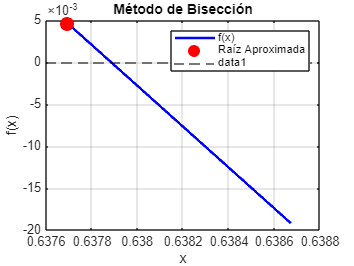


% ---------- GRAFICAR LA FUNCIÓN ----------

% Crear un vector de valores para graficar la función
x_vals = linspace(a, b, 1000);  % Intervalo de la gráfica
y_vals = arrayfun(f, x_vals);   % Evaluar la función en esos puntos

% Graficar la función
figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);  % Graficar la función
hold on;
grid on;

% Marcar la raíz encontrada en la gráfica
plot(puntoMedioActual, f(puntoMedioActual), 'ro', 'MarkerSize', 10, 'MarkerFaceColor', 'r');

% Añadir etiquetas y título
xlabel('x');
ylabel('f(x)');
title('Método de Bisección');
legend('f(x)', 'Raíz Aproximada');

% Marcar el eje x
yline(0, 'k--');